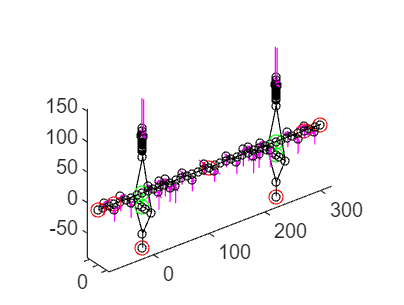

ans =   Figure (36) - 属性:

      Number: 36
        Name: ''
       Color: [1 1 1]
    Position: [440 338 560 420]
       Units: 'pixels'

  显示 所有属性


bridge_noncable = bridge_state.clone;
bridge_noncable.OutputMethod = OutputToAnsys(bridge_noncable,"JobName",'TotalModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\test\BaseModelAddCable',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\test\BaseModelAddCable\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\test\BaseModelAddCable\result.out');
% 1. 先导出无索模型（也无集中力），作为BaseModel
bridge_noncable.plot

outputBaseModel(bridge_noncable)
resumeCableSystem(bridge_noncable)
% 2. 计算斜拉索、吊索、主缆此时的坐标和初应变
% 计算吊索力和主缆内力
Y_final = bridge_noncable.solveCableShape(Pz_final);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.694234e+03    0.000e+00    4.339e+02
    1      12    7.537403e+01    0.000e+00    1.075e+02    8.243e+00
    2      18    1.434658e+01    0.000e+00    1.753e+01    4.303e+00
    3      24    9.827357e+00    0.000e+00    7.274e+00    4.284e+00
    4      31    3.363543e+00    0.000e+00    1.111e+01    2.501e+00
    5      37    1.900621e+00    0.000e+00    4.285e+00    2.033e+00
    6      43    1.437081e+00    0.000e+00    5.649e+00    1.652e+00
    7      49    1.751542e-01    0.000e+00    2.970e+00    9.291e-01
    8      56    1.104684e-01    0.000e+00    9.823e-01    2.815e-01
    9      62    2.622057e-02    0.000e+00    1.487e+00    2.629e-01

fmincon 已停止，因为目标函数值 2.622057e-02 小于
options.ObjectiveLimit = 5.000000e-02，
且相对最大约束违反值 0.000000e+00 小于 <a hre

ans = 包含以下字段的 struct :
                   X: [0 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240]
                   Y: [-1 -2.2997 -3.5994 -4.8991 -6.1988 -7.0217 -7.8445 -8.6673 -9.4902 -9.8144 -10.1387 -10.4629 -10.7871 -10.4627 -10.1383 -9.8139 -9.4895 -8.6636 -7.8378 -7.0119 -6.1860 -4.8895 -3.5930 -2.2965 -1]
                   Z: [101.8000 86.3401 71.7468 57.9865 45.0277 36.5048 28.6029 21.3037 14.5907 11.4506 8.8093 6.6607 5.0000 6.6607 8.8093 11.4506 14.5907 21.3037 28.6029 36.5049 45.0278 57.9866 71.7469 86.3402 101.8000]
              Strain: [1.4765e-04 1.4189e-04 1.3646e-04 1.3134e-04 1.0530e-04 1.0216e-04 9.9244e-05 9.6560e-05 8.3872e-05 8.2765e-05 8.1847e-05 8.1118e-05 8.1118e-05 8.1847e-05 8.2765e-05 8.3872e-05 9.6562e-05 9.9245e-05 1.0216e-04 1.0530e-04 … ]
    UnstressedLength: [18.4558 17.7366 17.0580 16.4186 13.1643 12.7712 12.4074 12.0720 10.4865 10.3481 10.2335 10.1423 10.1423 10.2334 10.3481 10.4865 12.0722 12.4076 12.7714 13

resumeSymmetrical called!


data_container = DataContainer();
data_container.Data.Y_0 = Y_final;

% 计算斜拉索索力
X = bridge_noncable.XCoordOfPz;
for i=1:length(bridge_noncable.ReplacedStayedCable)
    stayed_cable = bridge_noncable.ReplacedStayedCable(i);
    Point_Bottom = stayed_cable.findGirderPoint();
    X_Bottom = [Point_Bottom.X];
    P_girder_z = zeros(1,length(X_Bottom));
    for j=1:length(X)
        index = abs(X(j)-X_Bottom) < 1e-5;
        P_girder_z(index) = Pz_final(j);
    end
    stayed_cable.getP(P_girder_z);
end
outputCableSystem(bridge_noncable,[1,0,0])

points = [];
lines = [];
StrucutreList = bridge_noncable.StructureList;
for i=1:length(StrucutreList)
    if strcmp(class(StrucutreList{i}),'StayedCable') || strcmp(class(StrucutreList{i}),'Hanger')
        points = [points,StrucutreList{i}.findGirderPoint];
        lines = [lines,StrucutreList{i}.Line];
    else
        continue
    end
end
[~,index] = points.sort('X');
sorted_lines = lines(index);
Map_line = bridge_noncable.Params.Map_MatlabLine2AnsysLine;
Map_elem = bridge_noncable.Params.Map_MatlabLine2AnsysElem;
num_line = cell2mat(values(Map_line,num2cell([sorted_lines.Num])))

num_line =    133   135   134   136   125   127   221   226   126   128   222   227   223   228   224   229   129   131   225   230   130   132   137   139   138   140


num_elem = cell2mat(values(Map_elem,num2cell([sorted_lines.Num])))

num_elem =    493   495   494   496   485   487   581   586   486   488   582   587   583   588   584   589   489   491   585   590   490   492   497   499   498   500


outputAnsysIPC(bridge_noncable,num_elem);


function outputBaseModel(obj)
    OutputMethod = obj.OutputMethod;
    OutputMethod.JobName = 'BaseModel';

    obj.OutputMethod.OutputObj = obj.OriginalBridge;
    OutputMethod.outputElementType();
    OutputMethod.outputMaterial();
    OutputMethod.outputSection();

    obj.OutputMethod.OutputObj = obj;
    OutputMethod.outputReal();
    OutputMethod.outputKeyPoint();
    OutputMethod.outputLine();
    OutputMethod.outputLineAttribution();
    OutputMethod.outputLineMesh();
    OutputMethod.outputConstraint();
    OutputMethod.outputCoupling();

    OutputMethod.outputMain('main_Base.mac','flag_Load',false,'flag_Solve',false);
end

function resumeCableSystem(obj)
    % 隐藏梁塔及其荷载和约束
    func = @(structure) [structure]; % function_handle，通过cellfun将cell转换为对象数组
    [girder_list,index_girder] = obj.findStructureByClass('Girder');
    obj.ReplacedGirder = cellfun(func,girder_list);
    [tower_list,index_tower] = obj.findStructureByClass('Tower');
    obj.ReplacedTower = cellfun(func,tower_list);
    [rigid_list,index_rigid] = obj.findStructureByClass('RigidBeam');
    obj.ReplacedRigidBeam = cellfun(func,rigid_list);

    replaced_structure_index = index_girder | index_tower | index_rigid;
    obj.MaterialList(replaced_structure_index) = [];
    obj.SectionList(replaced_structure_index) = [];
    obj.ElementTypeList(replaced_structure_index) = [];
    obj.ElementDivisionList(replaced_structure_index) = [];
    obj.StructureList(replaced_structure_index) = [];
    
    
    % 恢复
    for i=1:length(obj.ReplacedStayedCable)
        member = obj.ReplacedStayedCable(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end
    for i=1:length(obj.ReplacedCable)
        member = obj.ReplacedCable(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end
    for i=1:length(obj.ReplacedHanger)
        member = obj.ReplacedHanger(i);
        obj.updateList('Structure',member,'Section',member.Section.unique, ...
                       'Material',member.Material,'ElementType',member.ElementType,'ElementDivision',member.ElementDivisionNum)
    end

    % 恢复
    couplings = obj.DeletedCoupling;
    constraints = obj.DeletedConstraint;

    cell2array = @(c) [c];
    obj.DeletedCoupling = cellfun(cell2array,obj.CouplingList);
    obj.DeletedConstraint = cellfun(cell2array,obj.ConstraintList);

    array2cell = @(c) {c};
    obj.CouplingList = arrayfun(array2cell,couplings);
    obj.ConstraintList = arrayfun(array2cell,constraints);

end

function outputCableSystem(obj,nsubst)
    OutputMethod = obj.OutputMethod;
    OutputMethod.JobName = 'CableSystem';
    Map_OutputedPoint = obj.Params.Map_OutputedPoint;
    Map_MatlabLine2AnsysLine = obj.Params.Map_MatlabLine2AnsysLine;
    Map_AnsysLine2MatlabLine = obj.Params.Map_AnsysLine2MatlabLine;
    Map_MatlabLine2AnsysElem = obj.Params.Map_MatlabLine2AnsysElem;
    Map_AnsysElem2MatlabLine = obj.Params.Map_AnsysElem2MatlabLine;

    num_start_line = max(cell2mat(keys(Map_AnsysLine2MatlabLine)))+1;
    num_start_elem = max(cell2mat(keys(Map_AnsysElem2MatlabLine)))+1;

    OutputMethod.outputReal('defReal_CableSystem.mac');
    OutputMethod.outputKeyPoint('defKeyPoint_CableSystem.mac',Map_OutputedPoint);
    OutputMethod.outputLine('defLine_CableSystem.mac',num_start_line,Map_MatlabLine2AnsysLine,Map_AnsysLine2MatlabLine);
    OutputMethod.outputLineAttribution('defLineAttribution_CableSystem.mac');
    OutputMethod.outputLineMesh('defLineMesh_CableSystem.mac',num_start_elem,Map_MatlabLine2AnsysElem,Map_AnsysElem2MatlabLine);
    OutputMethod.outputConstraint('defConstraint_CableSystem.mac');
    OutputMethod.outputCoupling('defCoupling_CableSystem.mac');
    output_str = ['/prep7',newline,...
                  'resume,BaseModel,db',newline,...
                  '/input,defReal_CableSystem,mac,,,0',newline,...
                  '/input,defKeyPoint_CableSystem,mac,,,0',newline,...
                  '/input,defLine_CableSystem,mac,,,0',newline,...
                  '/input,defLineAttribution_CableSystem,mac,,,0',newline,...
                  '/input,defLineMesh_CableSystem,mac,,0',newline,...
                  '/input,defConstraint_CableSystem,mac,,,0',newline,...
                  '/input,defCoupling_CableSystem,mac,,,0',newline];
    obj.OutputMethod.outputAPDL(output_str,'main_CableSystem.mac','w');
end